% using MDL and AIC to find source number, and ESPRIT to find DOAs
clear(); close all;

wavelength = 1; % normalized
d = wavelength / 2;
design_ula = design_array_1d('ula', 6, d);
doas = [0, 0.5];
power_source = 1;
SNR_dB = -5;
power_noise = power_source / (10^(SNR_dB/10));
snapshot_count = 1000;
source_count = length(doas);

% stochastic (unconditional) model
[~, R] = snapshot_gen_sto(design_ula, doas, wavelength, snapshot_count, power_noise, power_source);

% source number detection
[~, l] = eig(0.5*(R+R'), 'vector');
l = flipud(l);
n_mdl = sn_mdl(l, design_ula.element_count, snapshot_count);
n_aic = sn_aic(l, design_ula.element_count, snapshot_count);
fprintf('There are %d sources.\n', source_count);

There are 2 sources.


fprintf('# of sources estimated by MDL = %d\n', n_mdl);

# of sources estimated by MDL = 2


fprintf('# of sources estimated by AIC = %d\n', n_aic);

# of sources estimated by AIC = 2



% ESPRIT
tic;
k = 2 * pi * d / wavelength; % Calculate k for ESPRIT
sp_esprit = esprit_1d(R, source_count, k, 'Unit', 'radian', 'Formulation', 'LS');
toc;

历时 0.000929 秒。


sp_esprit.true_positions = doas;
fprintf('[ESPRIT] Estimated DOAs:\n');

[ESPRIT] Estimated DOAs:


disp(sp_esprit.x_est);

    0.0012
    0.4976



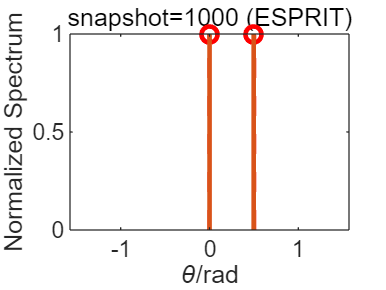


% Plot the spectrum
plot_sp(sp_esprit, 'title', 'snapshot=1000 (ESPRIT)', 'PlotType', 'cartesian', 'LineWidth', 1.75);